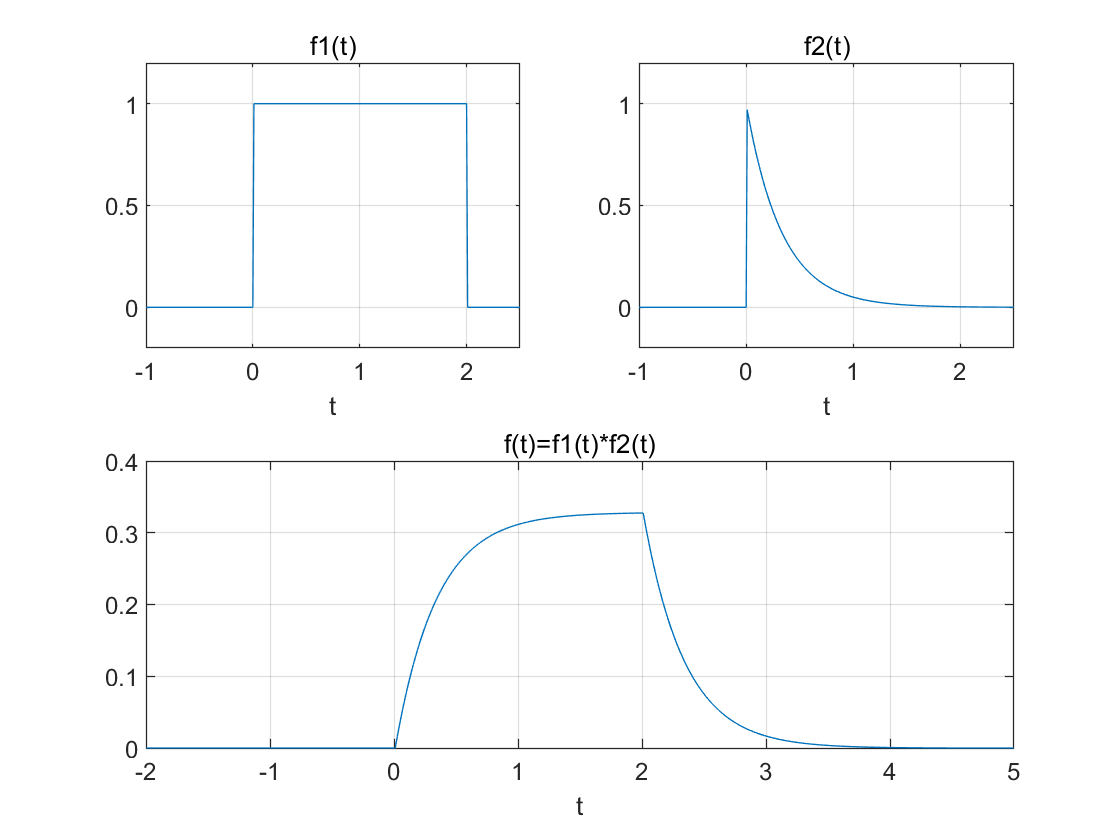

dt=0.01; t=-1:dt:2.5;
f1=Heaviside(t)-Heaviside(t-2);
f2=exp(-3*t).*Heaviside(t);
f=conv(f1,f2)*dt; n=length(f); tt=(0:n-1)*dt-2;
subplot(221), plot(t,f1), grid on;
axis([-1,2.5,-0.2,1.2]); title('f1(t)'); xlabel('t')
subplot(222), plot(t,f2), grid on;
axis([-1,2.5,-0.2,1.2]); title('f2(t)'); xlabel('t')
subplot(212), plot(tt,f), grid on;
title('f(t)=f1(t)*f2(t)'); xlabel('t')